## Generate 4-QAM Image Data

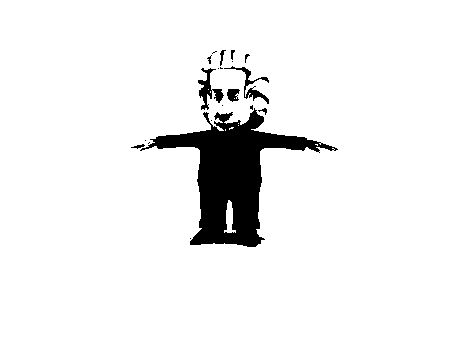

im = imread('data\einstein.jpg');
imBW = im2bw(im,.7);
figure;
imshow(imBW)

## Generate TX Data

clear;
hamming_on = 0;
picture = 'einstein';
%generate start sequence
input_image = strcat('data\',picture,'.jpg');
pilot_seq_len = 32; % length of known pilot sequence
%ending_seq_len = 32;
standard_packet_len = 100000;
Fs = 2000000; % sampling frequency

%generate RRC Pulse
T = 50; % Symbol Period
data_len = standard_packet_len * T;
span = 20;
rolloff = 0.5;
rrc = rcosdesign(rolloff,span,T, 'sqrt');   % creates a root-raised cosine 

[imBW,dataQ,data] = image_to_data(input_image,hamming_on);

% if hamming_on
%     txname = strcat('data\', picture, '_hamming11pm.dat');
% else
%     txname = strcat('data\', picture, '_11pm.dat');
% end
% txname
% input = build_tx_file(txname, dataQ, pilot_seq_len, rrc, T, standard_packet_len)

## Decode RX Data

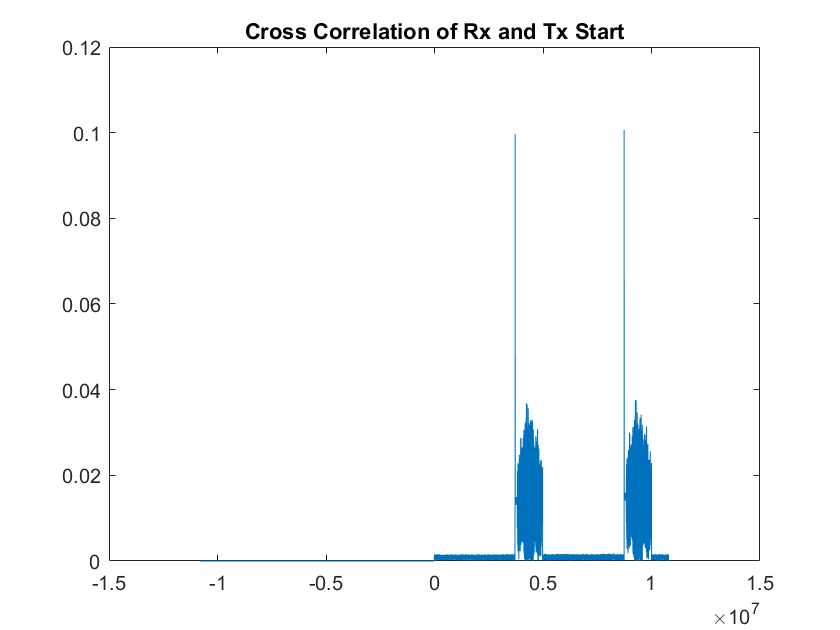

tx_pilot =   -0.1281 + 0.1298i
  -0.1266 + 0.1283i
  -0.1248 + 0.1265i
  -0.1225 + 0.1242i
  -0.1199 + 0.1215i
  -0.1168 + 0.1184i
  -0.1134 + 0.1149i
  -0.1095 + 0.1109i
  -0.1053 + 0.1066i
  -0.1008 + 0.1020i


startPos = 8739338

startPos = 8739338

rx_pilot =   -0.6409 - 0.4273i
  -0.4883 - 0.0916i
  -0.2136 - 0.0305i
  -0.0610 - 0.1221i
  -0.0916 - 0.3967i
  -0.3357 - 0.6104i
  -0.6409 - 0.5493i
  -0.8240 - 0.1831i
  -0.5188 + 0.1221i
  -0.0610 + 0.0916i


a =    0.1896 + 0.9819i
   0.5591 + 0.8291i
   0.5946 + 0.8040i
  -0.3226 + 0.9465i
  -0.5357 + 0.8444i
  -0.2852 + 0.9585i
   0.0702 + 0.9975i
   0.5315 + 0.8471i
   0.8470 + 0.5315i
   0.9817 - 0.1904i


diff = 1.3954

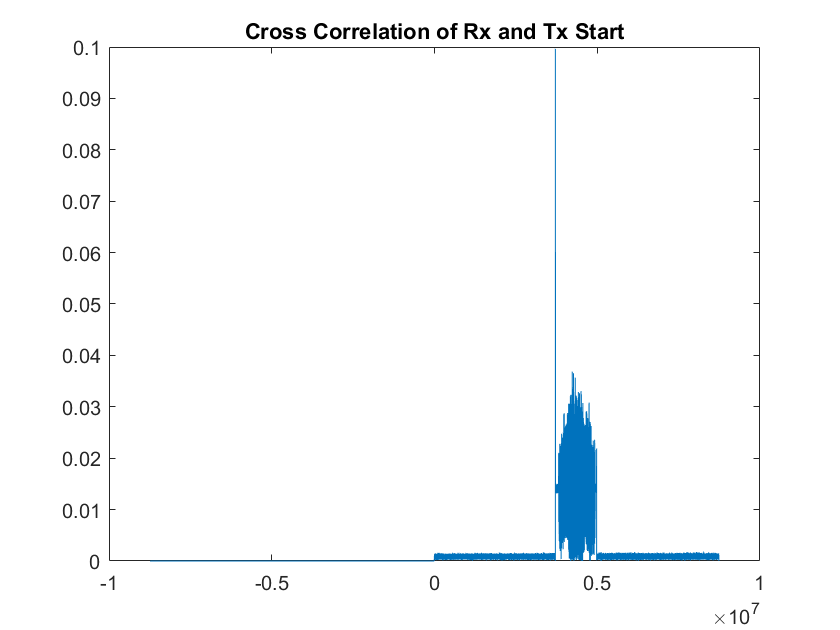

tx_pilot =   -0.1281 + 0.1298i
  -0.1266 + 0.1283i
  -0.1248 + 0.1265i
  -0.1225 + 0.1242i
  -0.1199 + 0.1215i
  -0.1168 + 0.1184i
  -0.1134 + 0.1149i
  -0.1095 + 0.1109i
  -0.1053 + 0.1066i
  -0.1008 + 0.1020i


startPos = 3713818

startPos = 3713818

rx_pilot =    0.0000 - 0.1831i
   0.1221 - 0.1221i
   0.2747 - 0.2441i
   0.3052 - 0.6104i
   0.0305 - 0.7935i
  -0.3052 - 0.6409i
  -0.3662 - 0.2441i
  -0.0916 + 0.0916i
   0.3662 + 0.0916i
   0.6409 - 0.2441i


a =   -0.7118 + 0.7024i
  -1.0000 - 0.0067i
  -0.9979 - 0.0655i
  -0.9508 + 0.3098i
  -0.7383 + 0.6745i
  -0.3407 + 0.9402i
   0.1897 + 0.9818i
   1.0000 + 0.0063i
  -0.5093 - 0.8606i
  -0.9101 - 0.4143i


diff = 2.6931

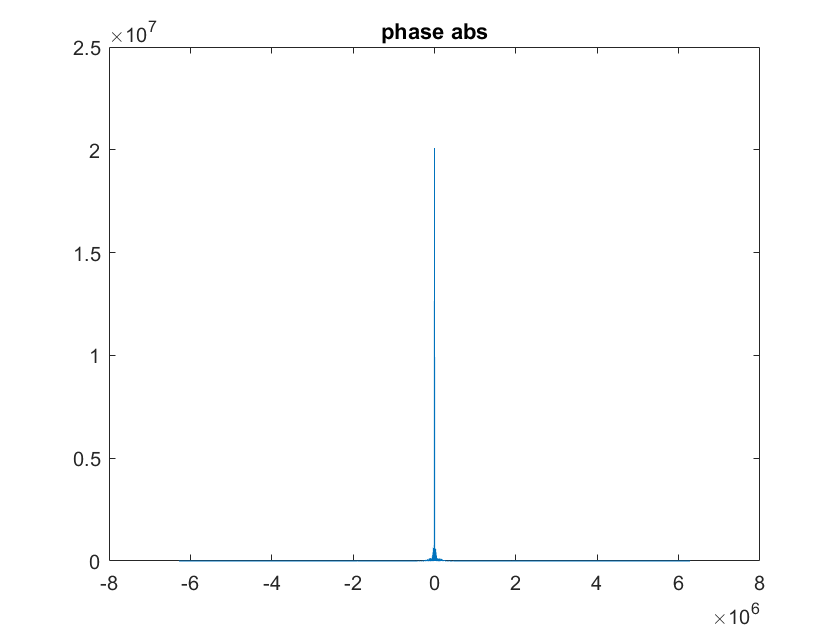

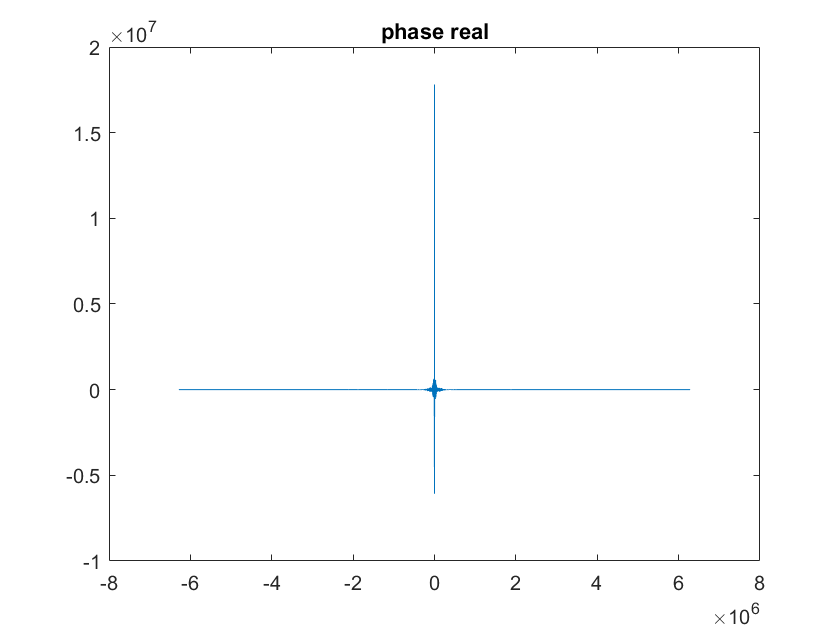

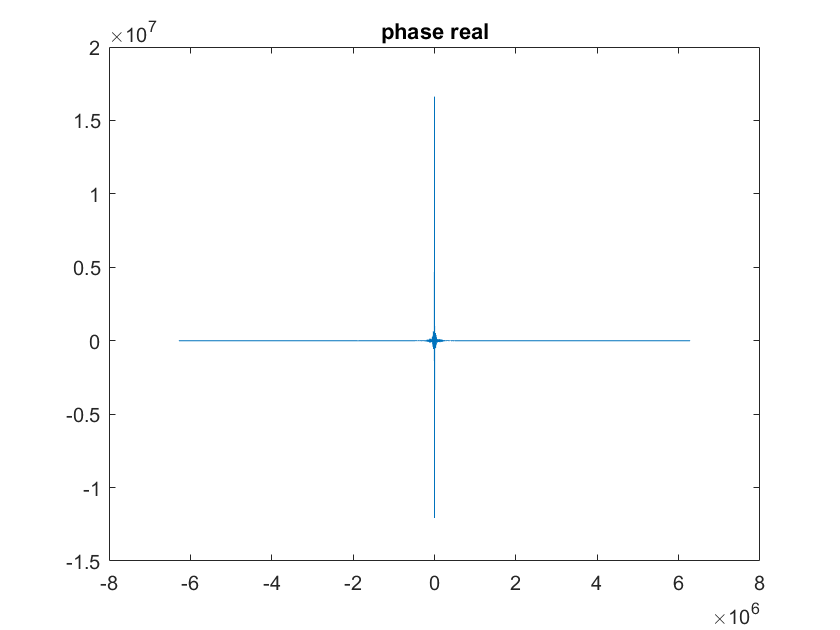

phi = -2.2124

err_total = 2052

err_total = 2256

err_total = 2418

err_total = 782

err_total = 1148

err_total = 944

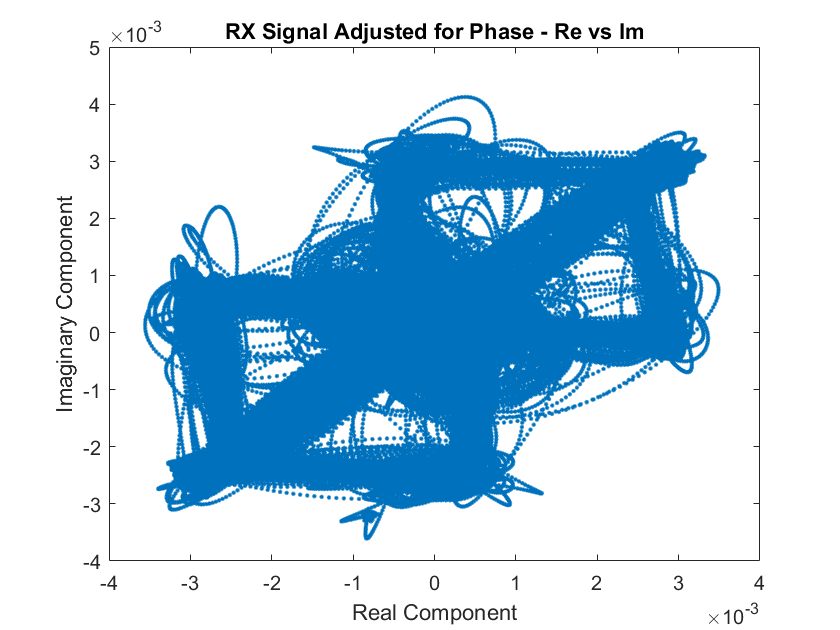

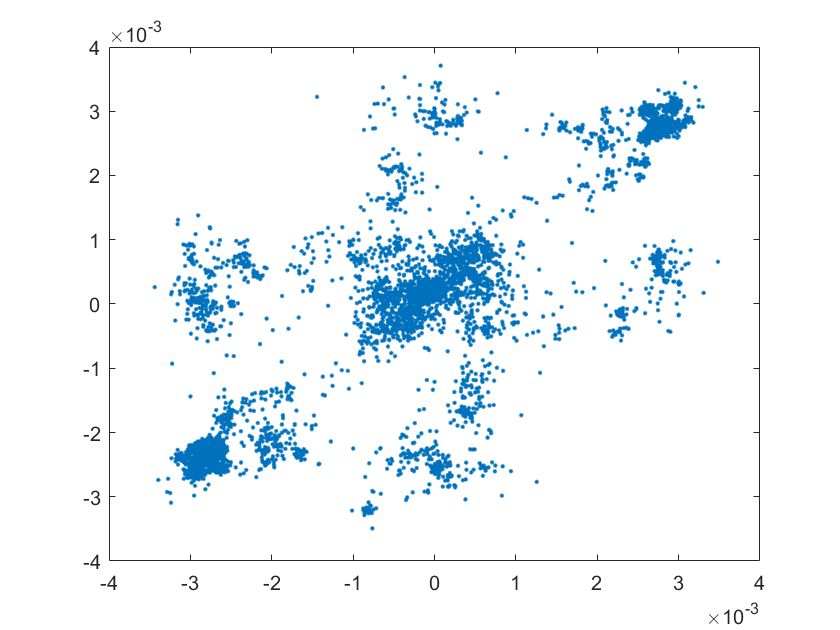

tx_ds =    0.9122 + 0.9170i
   0.8795 + 0.8950i
   0.8206 + 0.7968i
   1.0729 + 1.0078i
  -1.1868 - 0.9070i
   1.2564 - 0.9535i
  -1.2002 + 0.9589i
   1.0332 + 0.8070i
   0.8384 + 0.9160i
   0.8922 + 0.8849i


rx_ds =    0.0016 + 0.0017i
   0.0031 + 0.0030i
   0.0022 + 0.0023i
  -0.0011 - 0.0005i
   0.0004 + 0.0011i
  -0.0005 + 0.0010i
   0.0005 - 0.0004i
  -0.0004 + 0.0020i
   0.0026 + 0.0031i
   0.0030 + 0.0029i


err_total = 160325

txname='data\einstein_11pm.dat';
rxname = 'data\rx_einstein_11pm.dat';
figure;
[rxQ, errRate] = qpsk(txname, rxname, T, 2000000, data_len);   

errRate

errRate = 0.8019

## Printing Image

rxQ = sign(real(rxQ)) + 1i*sign(imag(rxQ));
rxBinary = decodeQam(rxQ);

if hamming_on
    rxBinary = errorCorrect(rxBinary);
end
 
rows = bi2de(rxBinary(1:16),'left-msb');
cols = bi2de(rxBinary(17:32),'left-msb');

if mod(rows*cols,2) ~= 0
    dataRx = rxBinary(33:end-1);
else
    dataRx = rxBinary(33:end);
end
dataRx = dataRx(1:216*233)

dataRx =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


compute_qpsk_error(data,dataRx)

err_total = 10742

ans = 0.1067

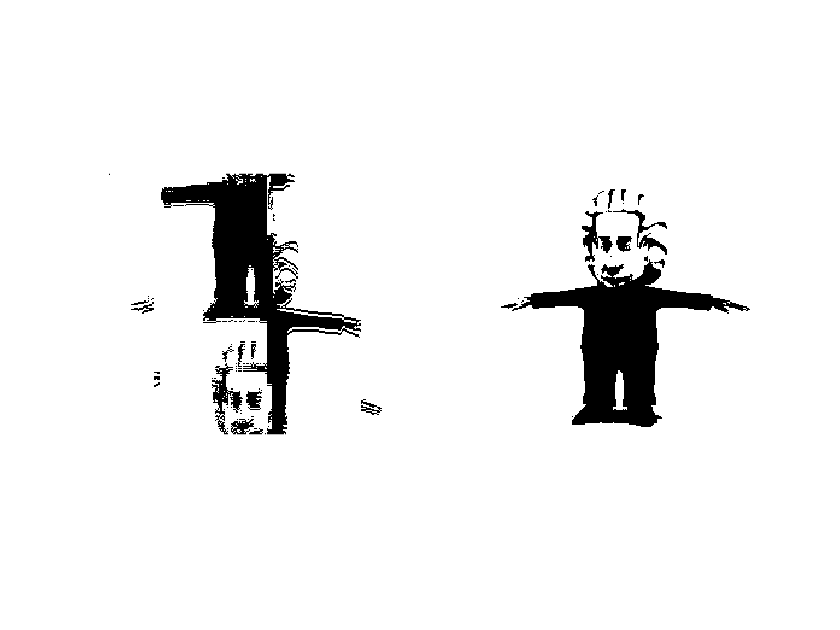

rxIm = reshape(dataRx, 216, []);
figure;
subplot(1,2,1)
imshow(rxIm)
subplot(1,2,2)
imshow(imBW)